# Hands-On -  AR(1)  Stochastic Process: Stationary vs. Non-Stationary Process

## Introduction

Consider the AR(1) process


$$v(t) = a \, v(t-1) +  \eta(t) \qquad \eta(\cdot) \sim WN(0,\lambda^2)$$


Recalling that $\vert a \vert <1$  and setting $v_{0} = v(t_0) \;,\quad t_0 = 0$ . Then, in general, we can write


$$v(t) =  \sum_{i=0}^{t-1} \, a^{t-1-i} \, \eta(i+1) + a^{t} \, v_{0}$$


Now suppose to generate $N$ samples for the r.v. of the AR process. Compare the results obtained using the following strategies

- Collect $N$ samples, starting from the time instant $t_0$;

- Collect $N_{skip} +N$ samples, starting from the time instant $t_0$, but then throw away the first $N_{skip}$ samples, in order to avoid data containig the transient response depending on the initial condition. Use only the remaining $N$ samples, as data of the steady-state stationary stochastic process. 

clear variables
close all
clc


## The AR(1) Process

Select the AR(1) parameter $a$, such that $\vert a \vert <1$

a_AR = 0.8; % select a value in the interval ]-1 , +1[

Tune the variance of the white noise $\lambda^2$

varWG = 4;      % select the white noise variance

Set as initial condition $v_0$ a random value

v0 = 1e3*randn; % as initial condition a gaussian r.v., with 0 mean and unitary variance

Choose how many data to generate ($N_{tot}$ samples), how many to throw away after the generation ($N_{skip$ samples)  and how many of the generated values to keep ($N$ samples) 

Ndata = 3800;    % how many samples to generate and keep?

Nskip = 1500;   % how many samples to generate, but then ignore?

Ntot = Nskip+Ndata; % total num. of samples to generate

## Stationary vs. Non-Stationary Process

- Evaluate the average value, the sampled variance, the autocorrelation function and the spectrum using the $N$ data of the "stationary" process.

- Compare the results with the corresponding values you obtain when using the whole $N_{tot}$ data, with the transient due to the initial condition.

## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

### Generate and Collect the Samples

Remember


$$AR(1) \, \colon \quad
v(t) = a \, v(t-1) +  \eta(t)$$


Let's generate the data 

% the AR process
buffer = zeros(Nskip,1); % a buffer used to generate a stationary AR process, regardless of any possible initial condition
buffer(1) = v0;     % the initial condition 

AR1 = zeros(Ntot-Nskip+1,1);     % the buffer used to store the data belonging to the stationary AR process
ARbuffer = [buffer; AR1];        % merging the arrays

eta = sqrt(varWG)*randn(Ntot,1); % let's generate the white noise samples

% ---- the  AR(1) process ----
for ii = 2:Ntot
    ARbuffer(ii) = a_AR * ARbuffer(ii-1)+eta(ii);
end % for ii

AR1 = ARbuffer(Nskip+1:end); % skip the initial Nskip data 
                             % and use the remaining samples as AR
                             % stationary process

AR0 = ARbuffer; % use the whole dataset as "candidate" AR process

### Comparing Average Values and Variances

Let's estimate the mean value and the variance for the stationary AR process

av_valAR1 = mean(AR1)      % the average value for the stationary AR process

av_valAR1 = -0.2552

varAR1 = varWG/(1-a_AR.^2) % the theoretical variance of the stationary process 

varAR1 = 11.1111

sampled_varAR1 = var(AR1)  % the sampled variance

sampled_varAR1 = 11.3466

Using the whole dataset, the mean and the varaince assume different values

% check the average value using all the dataset
av_AR0 = mean(AR0)

av_AR0 = 0.6379


% check the variance
sampled_varAR0 = var(AR0)  % the sampled variance

sampled_varAR0 = 453.2263

Run more than once, varying the variance of the white noise feeding in. 

### **What About the Autocovariance Function?**

Ncorr1 =1024; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr1 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

[gamma_v1, lags_v1] = xcorr(AR1, Ncorr1,'unbiased'); 
% unbiased estimation of the autocovariance function

[gamma_v0, lags_v0] = xcov(AR0, Ncorr1,'unbiased'); 
% unbiased estimation of the autocorr. function of tilde_v

gammaAR1 = varAR1*(a_AR.^(abs(lags_v1))); % the true autocorrelation function of the stationary AR process


Now let's plot 

- the acquired samples of the AR(1) process

- the samples of the estimated autocovaraiance and autocorrelation function toghethere with the corresponding values of the theoretical expression of the autocovariance function

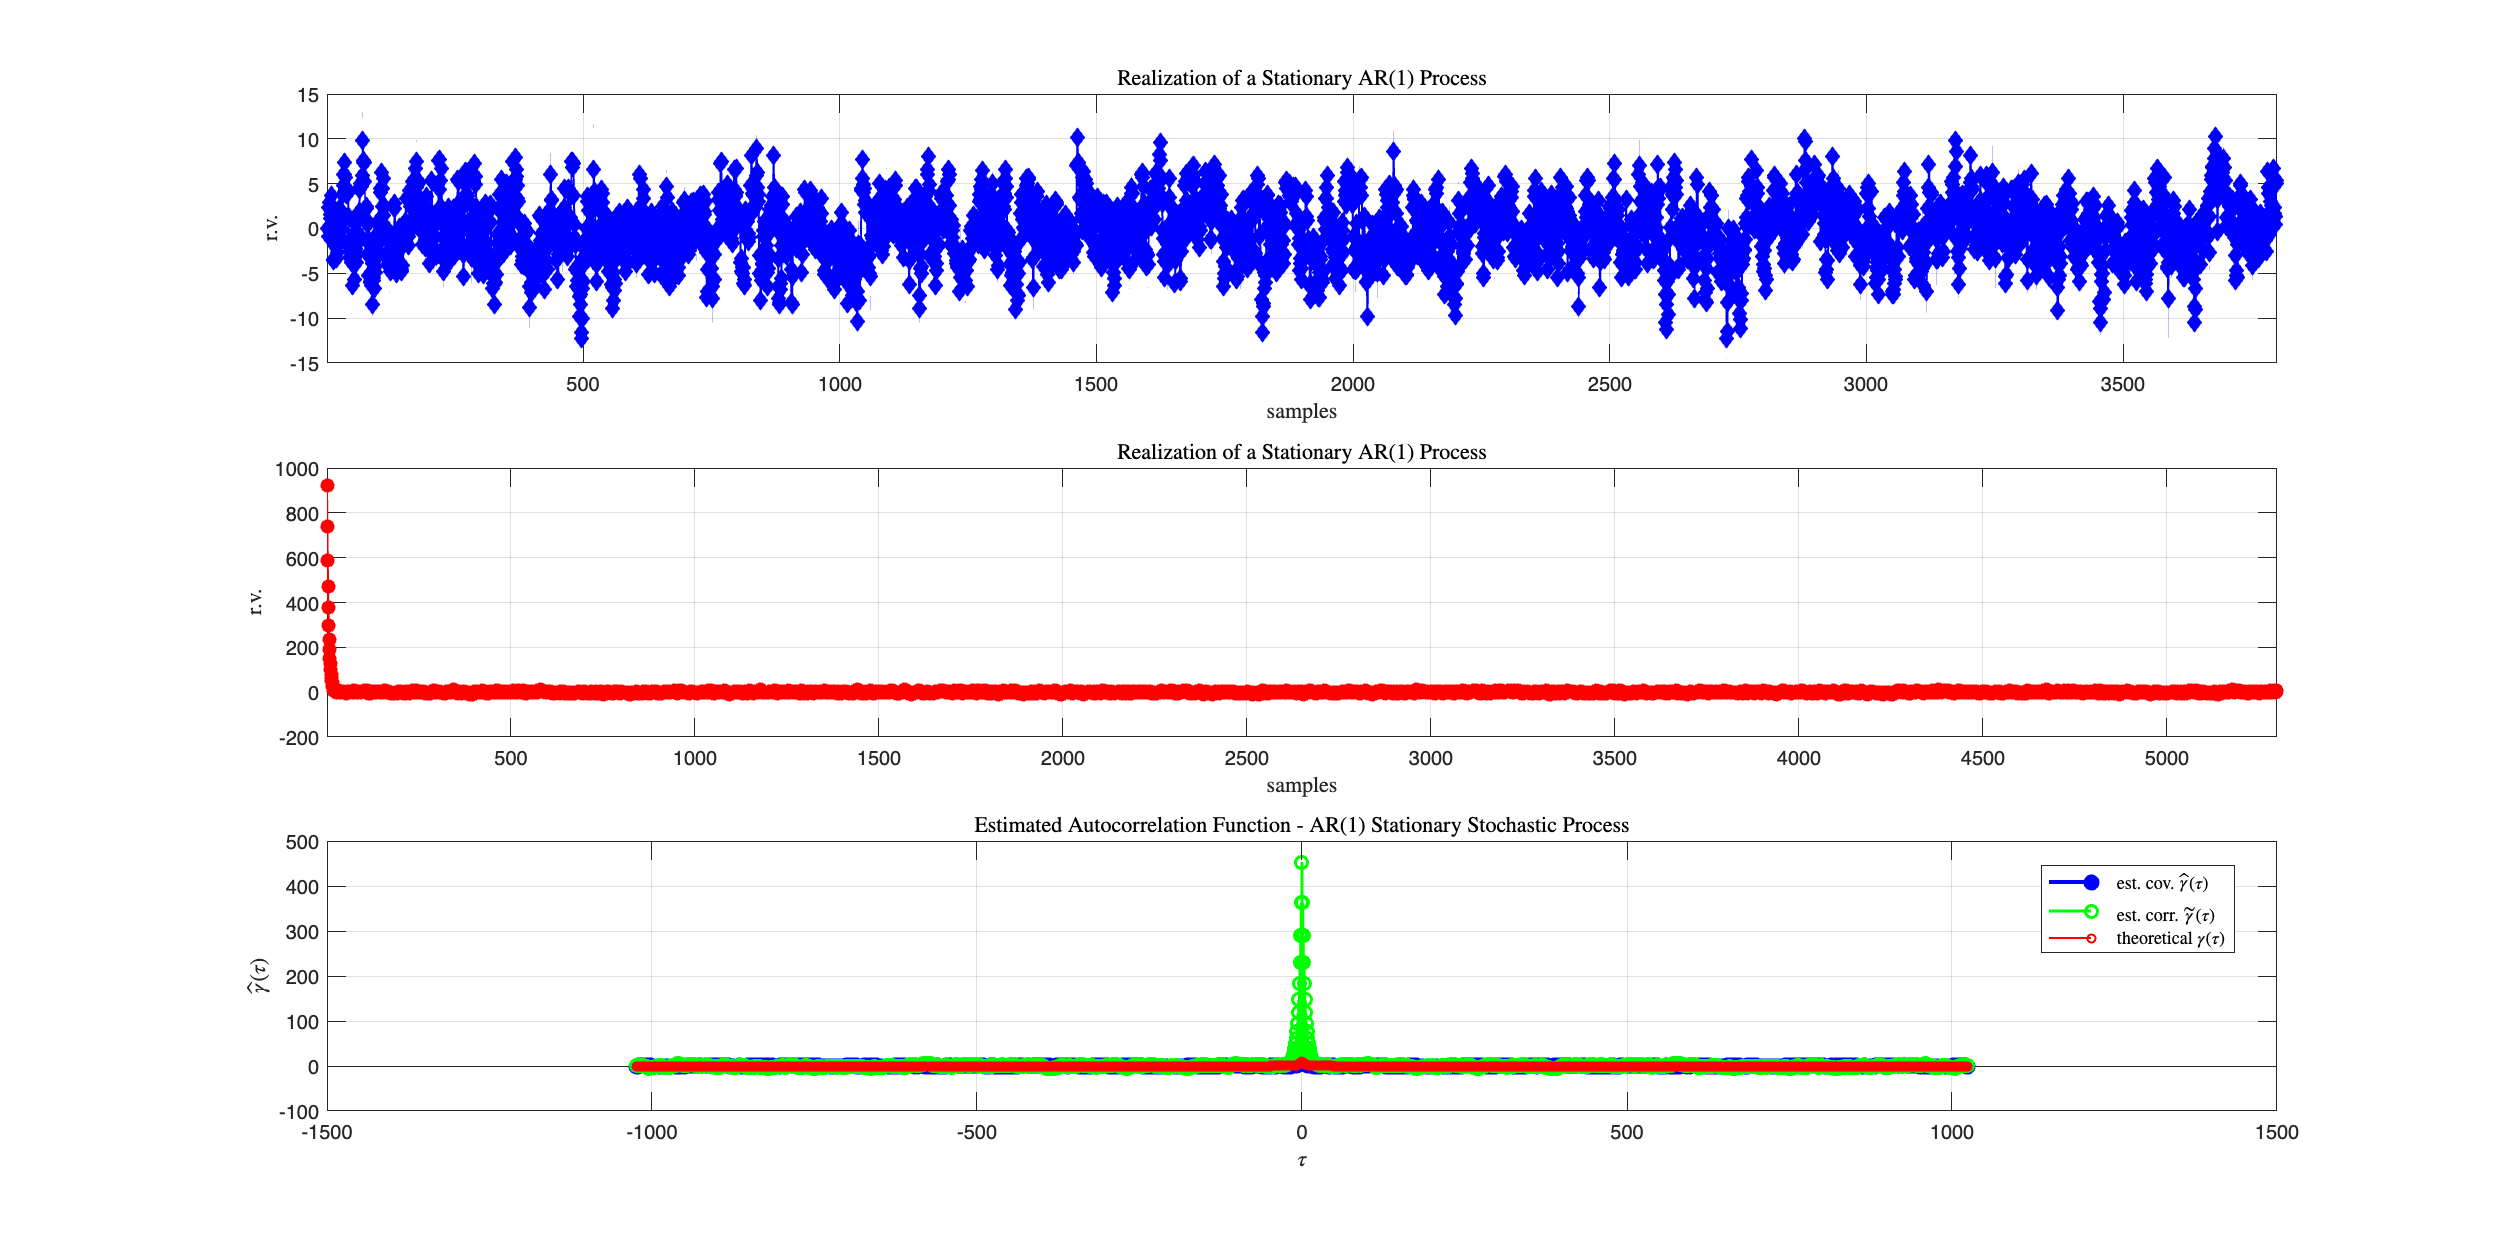

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(3,1,1);
plot(AR1,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary AR$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis[']]]=

subplot(3,1,2);

plot(AR0,'or-','MarkerSize',6, 'MarkerFaceColor','r','LineWidth',1.0);grid on;
title('Realization of a Stationary AR$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ntot]); % setting the extremum values on the x-axis[']]]=

subplot(3,1,3);
% the covariance function of v(t)
stem(lags_v1, gamma_v1,'b','filled', 'LineWidth',2);
grid on; hold on;

% the correlation function of tilde_v
stem(lags_v0, gamma_v0,'g', 'LineWidth',1.5);

% the theoretical expression of the covaraince function
stem(lags_v1, gammaAR1, 'r', 'MarkerSize',4,'LineWidth',1.0);
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - AR$(1)$ Stationary Stochastic Process',...
    'Interpreter','latex');
legend('est. cov. $\hat{\gamma}(\tau)$', 'est. corr. $\tilde{\gamma}(\tau)$','theoretical $\gamma(\tau)$', 'Location', 'best', 'Interpreter', 'latex')